# **Entrega Final: Frenado Magnetico**

## **Integrantes**

**Daniel Alfredo Barreras Meraz       A01254805**

**Daniel Antonio Luján                      A01254903**

**María Paula Rodríguez Muñoz       A01254734**

**Jorge Ivan Coronado Villegas       A01254785**

**José Víctor Symonds Rivera         A01254755**

**Roberto Enríquez Gómez **†**            A01252515**

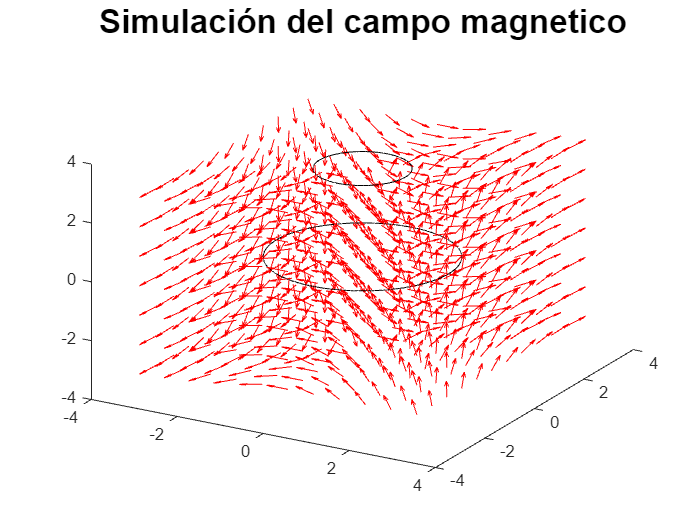

clear; clc; clf; close all;

% Constantes de la malla
x1 = -3; % Límite inferior del eje x (m)
x2 = 3; % Límite superior del eje x (m)
y1 = -3; % Límite inferior del eje y (m)
y2 = 3; % Límite superior del eje y (m)
nx = 0.6; % Espaciado entre puntos en el eje x (m)
ny = 0.6; % Espaciado entre puntos en el eje y (m)
z1 = -3; % Límite inferior del eje z (m)
z2 = 3; % Límite superior del eje z (m)
nz = 1; % Espaciado entre puntos en el eje z (m)

% MeshGrid
% Genera una malla de puntos en el espacio 3D con los límites y espaciados especificados anteriormente
[xGrid, yGrid, zGrid] = meshgrid(x1:nx:x2, y1:ny:y2, z1:nz:z2);

% Valores para las espiras
radioCirculo = 2; % Radio del círculo que representa la trayectoria de la góndola (m)
radioEspira = 1; % Radio de la espira que genera el campo magnético (m)
xEspira = -radioEspira:0.001:radioEspira; % Coordenadas x de los puntos que forman la espira (m)
yEspira = sqrt((radioEspira^2)-(xEspira.^2)); % Coordenadas y de los puntos que forman la espira (m)
xCirculo = -radioCirculo:0.001:radioCirculo; % Coordenadas x de los puntos que forman el círculo (m)
zEspira = zeros(length(xEspira)); % Coordenadas z de los puntos que forman la espira (m)
alturaEspira = 3; % Altura a la que se encuentra la espira respecto al suelo (m)
zEspira = zEspira + alturaEspira;
yCirculo = sqrt((radioCirculo^2)-(xCirculo.^2)); % Coordenadas y de los puntos que forman el círculo (m)

% Graficar el círculo y la espira
hold on;
title("Simulación del campo magnetico", "FontSize", 20);
plot(xCirculo, yCirculo, 'k', xCirculo, -yCirculo, 'k');
plot3(xEspira, yEspira, zEspira, 'k', xEspira, -yEspira, zEspira, 'k');

% Parámetros para el campo
M0 = 4.*pi.*10^-7; % Permeabilidad magnética del vacío (H/m)
I = 50; % Corriente eléctrica que circula por los conductores (A)
xn1 = -radioCirculo; % Posición x del primer conductor (m)
yn1 = 0; % Posición y del primer conductor (m)
xn2 = radioCirculo; % Posición x del segundo conductor (m)
yn2 = 0; % Posición y del segundo conductor (m)
r1 = sqrt(((xGrid - xn1).^2) + ((yGrid - yn1).^2)); % Distancia al primer conductor (m)
r2 = sqrt(((xGrid - xn2).^2) + ((yGrid - yn2).^2)); % Distancia al segundo conductor (m)

% Calcular el campo magnético generado por los conductores
[Cx, Cy, Cz]= calcularCampo(M0, xGrid, yGrid, [xn1 yn1], [xn2 yn2], I, [r1 r2]);

% Graficar el campo magnético con quiver3
quiver3(xGrid, yGrid, zGrid, Cx, Cy, Cz, 'r');
view(30, 30);
hold off;


% Valores iniciales para las gráficas
h = 0.2;
t = 0:h:5;
y = zeros(1, length(t));
z = zeros(1, length(t));
y(1) = 5;
z(1) = 5;
g = 9.81; % Aceleración debida a la gravedad (m/s^2)
m = 40; % Masa de la góndola (kg)
a = radioEspira; % Radio de la espira (m)
z = alturaEspira; % Altura de la espira respecto al suelo (m)
A = (a^2*pi); % Área de la espira (m^2)
R = 1; % Resistencia eléctrica de la espira (ohm)
masa = 1; % Masa del imán que cae en la dropTower (kg)
Et = 5; % Fuerza electromotriz inducida en la espira (V)
L = 3; % Inductancia de la espira (H)
C = 1; % Capacitancia del circuito (F)


### Ecuaciones diferenciales para calcular la velocidad y posición de la góndola en función del tiempo

La primera ecuación diferencial describe la velocidad de la góndola en función del tiempo

La segunda ecuación diferencial describe la aceleración de la góndola en función del tiempo

El primer término, -g, representa la aceleración debida a la gravedad

El segundo término representa la aceleración debida al frenado magnético, que se calcula utilizando las leyes de Faraday-Lenz y Lorentz

La ley de Faraday-Lenz establece que la fuerza electromotriz inducida en un circuito es igual a la tasa de cambio del flujo magnético a través del circuito

La ley de Lorentz establece que la fuerza sobre una partícula cargada en movimiento en un campo magnético es igual al producto cruz entre la carga de la partícula, su velocidad y el campo magnético

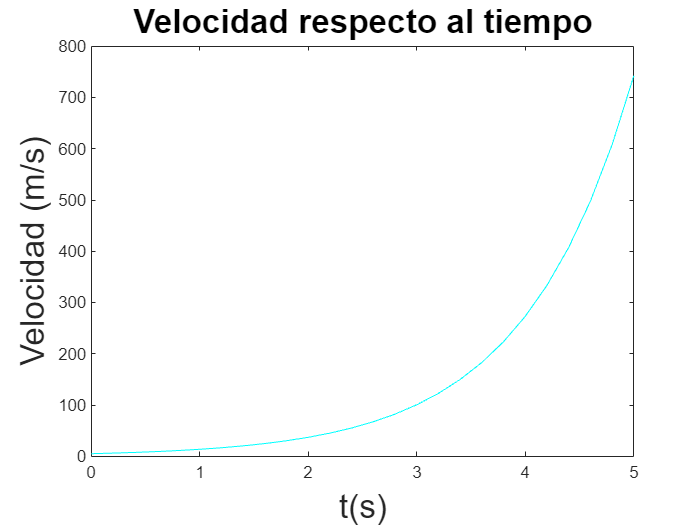

fy = @(t, vz, z) vz;
fz = @(t, vz, z) -g-(((27*M0^3*m^2*a^6*z*3*vz^2*A)/(4*R^2*(a^2 + z^2)^(7/2)))/masa);

[tt, yy, zz] = rk4(fy, fz, h, t, y, z);

% Graficar la velocidad respecto al tiempo
figure;
plot(tt, yy, 'c');
title("Velocidad respecto al tiempo", "FontSize", 20);
xlabel("t(s)", "FontSize", 20);
ylabel("Velocidad (m/s)", "FontSize", 20);

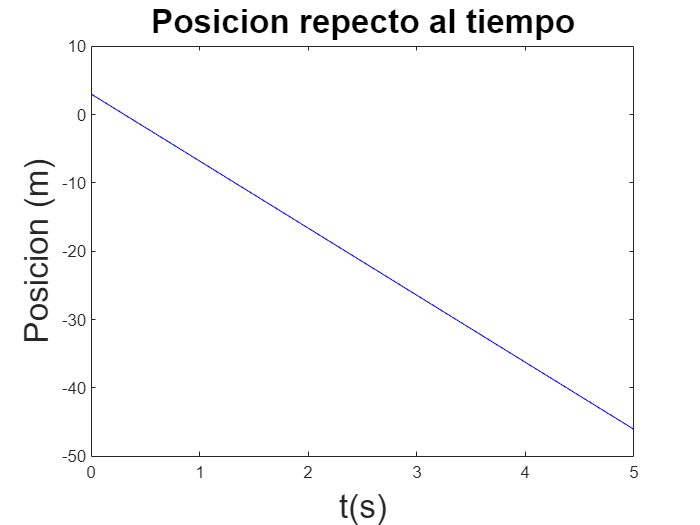


% Graficar la posición respecto al tiempo
figure;
plot(tt, zz, 'b');
title("Posicion repecto al tiempo", "FontSize", 20);
xlabel("t(s)", "FontSize", 20);
ylabel("Posicion (m)", "FontSize", 20);

### **Ecuaciones diferenciales para calcular la aceleración y corriente inducida en función del tiempo**

La primera ecuación diferencial describe cómo cambia la aceleración en función del tiempo

La segunda ecuación diferencial describe cómo cambia la corriente inducida en función del tiempo

Estas dos variables están relacionadas entre sí a través de la ley de Faraday-Lenz, que establece que la fuerza electromotriz inducida en un circuito es igual a la tasa de cambio del flujo magnético a través del circuito

En este caso, el circuito es la espira y el flujo magnético es el campo magnético generado por el imán que cae en la drop tower

La fuerza electromotriz inducida genera una corriente eléctrica en la espira, que a su vez genera un campo magnético opuesto al campo magnético del imán

La interacción entre estos dos campos magnéticos produce una fuerza de frenado sobre el imán, que se traduce en una aceleración negativa

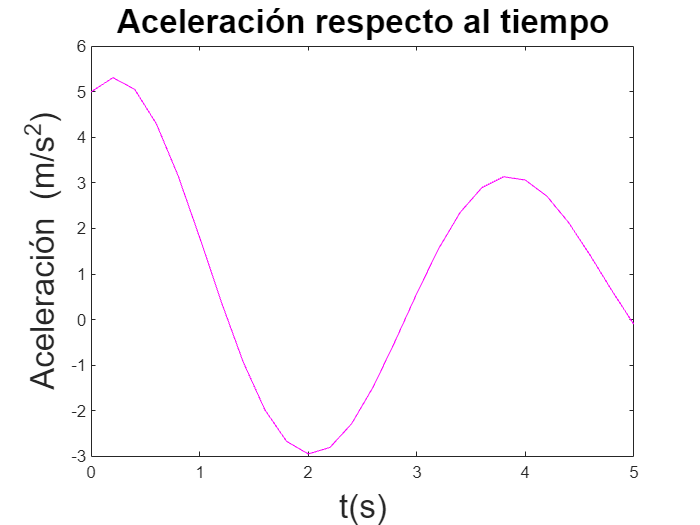

fy = @(t, a, I) I;
fz = @(t, a, I) (Et/L)-((R*I)/L)-a/C*L;

[tt, yy, zz] = rk4(fy, fz, h, t, y, z);

% Graficar la aceleración respecto al tiempo
figure;
plot(tt, yy, 'm');
title("Aceleración respecto al tiempo", "FontSize", 20);
xlabel("t(s)", "FontSize", 20);
ylabel("Aceleración (m/s^2)", "FontSize", 20);

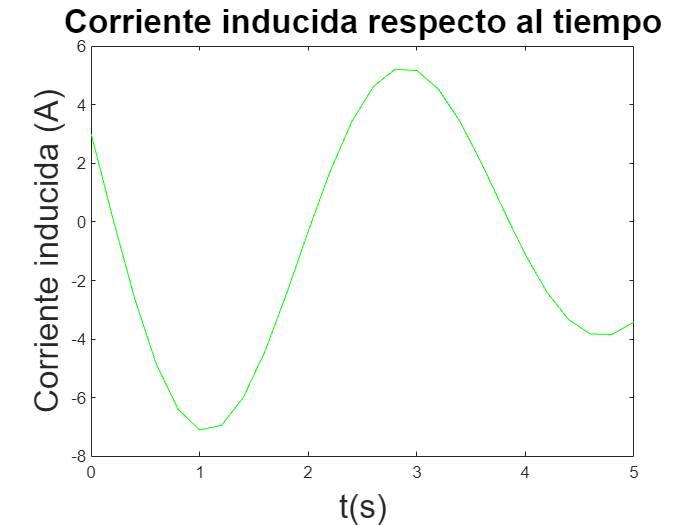


% Graficar la corriente inducida respecto al tiempo
figure;
plot(tt, zz, "Color", "green");
title("Corriente inducida respecto al tiempo", "FontSize", 20);
xlabel("t(s)", "FontSize", 20);
ylabel("Corriente inducida (A)", "FontSize", 20);

### Función para calcular el campo magnético generado por los conductores

function [Cx, Cy, Cz] = calcularCampo(M0, xGrid, yGrid, C1posicion, C2posicion, I, radio)
    % Ley de Biot-Savart para calcular el campo magnético generado por un conductor rectilíneo
    Cx = ((M0.*I.*(yGrid - C1posicion(2)))./(2.*radio(1).^2)) + ((M0.*I.*(yGrid - C2posicion(2)))./(2.*radio(1).^2));
    Cy = ((M0.*I.*(xGrid - C1posicion(1)))./(2.*radio(1).^2)) + ((M0.*I.*(xGrid - C2posicion(1)))./(2.*radio(1).^2));
    Cz = ((M0.*I.*(xGrid - C1posicion(1)))./(2.*radio(1).^2)) + ((M0.*I.*(xGrid - C2posicion(1)))./(2.*radio(1).^2));
    % Normalizar el campo magnético para graficarlo con quiver3
    C = sqrt(Cx.^2 + Cy.^2 + Cz.^2);
    Cx = Cx./C;
    Cy = Cy./C;
    Cz = Cz./C;
end


### Función para resolver un sistema de ecuaciones diferenciales de primer orden con el método de Runge-Kutta de cuarto orden

function[t, y, z] = rk4(eq1, eq2, h, t, y, z)
    for i = 1:length(t)-1
        k1 = eq1(t(i), y(i), z(i));
        k12 = eq2(t(i), y(i), z(i));
        k2 = eq1(t(i)+h/2, y(i)+((h/2)*k1), z(i)+((h/2)*k12));
        k22 = eq2(t(i)+h/2, y(i)+((h/2)*k1), z(i)+((h/2)*k12));
        k3 = eq1(t(i)+(h/2), y(i)+((h/2)*k2), z(i)+((h/2)*k22));
        k32 = eq2(t(i)+(h/2), y(i)+((h/2)*k2), z(i)+((h/2)*k22));
        k4 = eq1(t(i)+h, y(i)+(h*k3), z(i)+(h*k32));
        k42 = eq2(t(i)+h, y(i)+(h*k3), z(i)+(h*k32));
        % Calcular el siguiente valor de las variables dependientes con la fórmula de Runge-Kutta de cuarto orden
        y(i+1) = y(i)+(h/6)*((k1+(2*k2)+(2*k3)+k4));
        z(i+1) = z(i)+(h/6)*((k12+(2*k22)+(2*k32)+k42));
    end
end